clear; close all;

## DAB

% Main DAB struct
dab = struct();

### RS: DAB - US: DAB

dab(1).us = 'DAB';

load('results/splitter_dab_dab_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(1).in10.doa = abs(doa_meters_2(idx)) + 15;
dab(1).in10.labels = ones(length(dab(1).in10.doa),1);
dab(1).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_dab_dab_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
dab(1).in10m.doa = abs(doa_meters_2(idx)) + 15;
dab(1).in10m.labels = ones(length(dab(1).in10m.doa),1);
dab(1).in10m.corr = min(correlation_value(idx),[],2);

### RS: DAB - US: DVB-T

dab(2).us = 'DBV-T';

load('results/splitter_dab_dvbt_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(2).in10.doa = abs(doa_meters_2(idx)) + 15;
dab(2).in10.labels = ones(length(dab(2).in10.doa),1)*2;
dab(2).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_dab_dvbt_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
dab(2).in10m.doa = abs(doa_meters_2(idx)) + 15;
dab(2).in10m.labels = ones(length(dab(2).in10m.doa),1)*2;
dab(2).in10m.corr = min(correlation_value(idx),[],2);

### RS: DAB - US: LTE

dab(3).us = 'LTE';

load('results/splitter_dab_lte_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(3).in10.doa = abs(doa_meters_2(idx)) + 15;
dab(3).in10.labels = ones(length(dab(3).in10.doa),1)*3;
dab(3).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_dab_lte_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
dab(3).in10m.doa = abs(doa_meters_2(idx)) + 15;
dab(3).in10m.labels = ones(length(dab(3).in10m.doa),1)*3;
dab(3).in10m.corr = min(correlation_value(idx),[],2);

### RS: DAB - US: GSM

dab(4).us = 'GSM';

load('results/splitter_dab_gsm_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dab(4).in10.doa = abs(doa_meters_2(idx)) + 15;
dab(4).in10.labels = ones(length(dab(4).in10.doa),1)*4;
dab(4).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_dab_gsm_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
dab(4).in10m.doa = abs(doa_meters_2(idx)) + 15;
dab(4).in10m.labels = ones(length(dab(4).in10m.doa),1)*4;
dab(4).in10m.corr = min(correlation_value(idx),[],2);

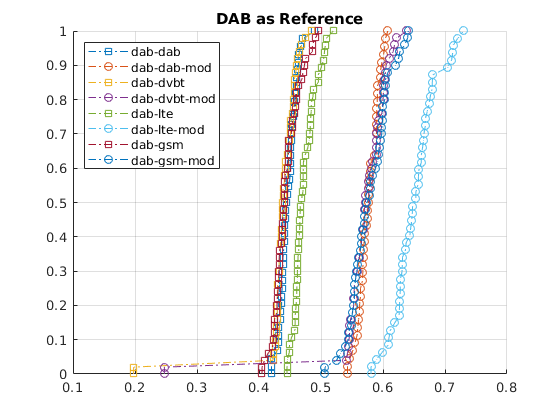

% Plotting
figure(); 
grid on; hold on;
[h{1},x{1}] = ecdf(dab(1).in10.corr); [hm{1},xm{1}] = ecdf(dab(1).in10m.corr);
[h{2},x{2}] = ecdf(dab(2).in10.corr); [hm{2},xm{2}] = ecdf(dab(2).in10m.corr);
[h{3},x{3}] = ecdf(dab(3).in10.corr); [hm{3},xm{3}] = ecdf(dab(3).in10m.corr);
[h{4},x{4}] = ecdf(dab(4).in10.corr); [hm{4},xm{4}] = ecdf(dab(4).in10m.corr);

for i = 1:4
    plot(x{i},h{i},'Marker',"square",'LineStyle',"-.");
    plot(xm{i},hm{i},'Marker',"o",'LineStyle',"-.");
end

legend('dab-dab','dab-dab-mod','dab-dvbt','dab-dvbt-mod','dab-lte','dab-lte-mod','dab-gsm','dab-gsm-mod','Location','northwest');
title('DAB as Reference');
hold off;

## DVB-T

% Main DAB struct
dvbt = struct();

### RS: DVB-T - US: DAB

dvbt(1).us = 'DAB';

load('results/splitter_dvbt_dab_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(1).in10.doa = abs(doa_meters_2(idx)) + 15;
dvbt(1).in10.labels = ones(length(dvbt(1).in10.doa),1)*5;
dvbt(1).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_dvbt_dab_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
dvbt(1).in10m.doa = abs(doa_meters_2(idx)) + 15;
dvbt(1).in10m.labels = ones(length(dvbt(1).in10m.doa),1)*5;
dvbt(1).in10m.corr = min(correlation_value(idx),[],2);

### RS: DVB-T - US: DVB-T

dvbt(2).us = 'DBV-T';

load('results/splitter_dvbt_dvbt_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(2).in10.doa = abs(doa_meters_2(idx)) + 15;
dvbt(2).in10.labels = ones(length(dvbt(2).in10.doa),1)*6;
dvbt(2).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_dvbt_dvbt_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
dvbt(2).in10m.doa = abs(doa_meters_2(idx)) + 15;
dvbt(2).in10m.labels = ones(length(dvbt(2).in10m.doa),1)*6;
dvbt(2).in10m.corr = min(correlation_value(idx),[],2);

### RS: DVB-T - US: LTE

dvbt(3).us = 'LTE';

load('results/splitter_dvbt_lte_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(3).in10.doa = abs(doa_meters_2(idx)) + 15;
dvbt(3).in10.labels = ones(length(dvbt(3).in10.doa),1)*7;
dvbt(3).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_dvbt_lte_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
dvbt(3).in10m.doa = abs(doa_meters_2(idx)) + 15;
dvbt(3).in10m.labels = ones(length(dvbt(2).in10m.doa),1)*7;
dvbt(3).in10m.corr = min(correlation_value(idx),[],2);

### RS: DVB-T - US: GSM

dvbt(4).us = 'GSM';

load('results/splitter_dvbt_gsm_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
dvbt(4).in10.doa = abs(doa_meters_2(idx)) + 15;
dvbt(4).in10.labels = ones(length(dvbt(4).in10.doa),1)*8;
dvbt(4).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_dvbt_gsm_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
dvbt(4).in10m.doa = abs(doa_meters_2(idx)) + 15;
dvbt(4).in10m.labels = ones(length(dvbt(2).in10m.doa),1)*8;
dvbt(4).in10m.corr = min(correlation_value(idx),[],2);

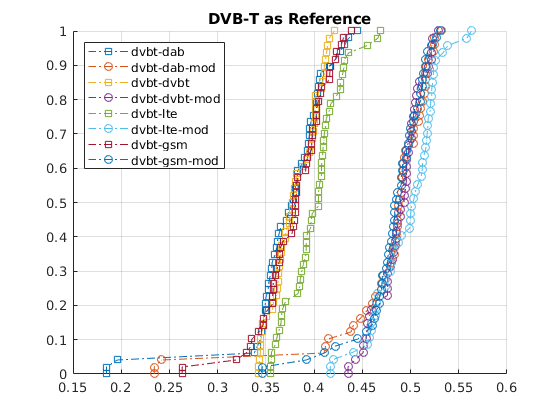

% Plotting
figure(); 
grid on; hold on;
[h{1},x{1}] = ecdf(dvbt(1).in10.corr); [hm{1},xm{1}] = ecdf(dvbt(1).in10m.corr);
[h{2},x{2}] = ecdf(dvbt(2).in10.corr); [hm{2},xm{2}] = ecdf(dvbt(2).in10m.corr);
[h{3},x{3}] = ecdf(dvbt(3).in10.corr); [hm{3},xm{3}] = ecdf(dvbt(3).in10m.corr);
[h{4},x{4}] = ecdf(dvbt(4).in10.corr); [hm{4},xm{4}] = ecdf(dvbt(4).in10m.corr);

for i = 1:4
    plot(x{i},h{i},'Marker',"square",'LineStyle',"-.");
    plot(xm{i},hm{i},'Marker',"o",'LineStyle',"-.");
end

legend('dvbt-dab','dvbt-dab-mod','dvbt-dvbt','dvbt-dvbt-mod','dvbt-lte','dvbt-lte-mod','dvbt-gsm','dvbt-gsm-mod','Location','northwest');
title('DVB-T as Reference');
hold off;

## GSM

% Main DAB struct
gsm = struct();

### RS: GSM - US: DAB

gsm(1).us = 'DAB';

load('results/splitter_gsm_dab_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(1).in10.doa = abs(doa_meters_2(idx)) + 15;
gsm(1).in10.labels = ones(length(gsm(1).in10.doa),1)*9;
gsm(1).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_gsm_dab_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
gsm(1).in10m.doa = abs(doa_meters_2(idx)) + 15;
gsm(1).in10m.labels = ones(length(gsm(1).in10m.doa),1)*9;
gsm(1).in10m.corr = min(correlation_value(idx),[],2);

### RS: GSM - US: DVB-T

gsm(2).us = 'DBV-T';

load('results/splitter_gsm_dvbt_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(2).in10.doa = abs(doa_meters_2(idx)) + 15;
gsm(2).in10.labels = ones(length(gsm(2).in10.doa),1)*10;
gsm(2).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_gsm_dvbt_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
gsm(2).in10m.doa = abs(doa_meters_2(idx)) + 15;
gsm(2).in10m.labels = ones(length(gsm(2).in10m.doa),1)*10;
gsm(2).in10m.corr = min(correlation_value(idx),[],2);

### RS: GSM - US: LTE

gsm(3).us = 'LTE';

load('results/splitter_gsm_lte_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(3).in10.doa = abs(doa_meters_2(idx)) + 15;
gsm(3).in10.labels = ones(length(gsm(3).in10.doa),1)*11;
gsm(3).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_gsm_lte_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
gsm(3).in10m.doa = abs(doa_meters_2(idx)) + 15;
gsm(3).in10m.labels = ones(length(gsm(3).in10m.doa),1)*11;
gsm(3).in10m.corr = min(correlation_value(idx),[],2);

### RS: GSM - US: GSM

gsm(4).us = 'GSM';

load('results/splitter_gsm_gsm_fo_correction_10_interp_dphase');
idx = min(correlation_value,[],2) > 0.1;
gsm(4).in10.doa = abs(doa_meters_2(idx)) + 15;
gsm(4).in10.labels = ones(length(gsm(4).in10.doa),1)*12;
gsm(4).in10.corr = min(correlation_value_interp(idx),[],2);

load('results/splitter_gsm_gsm_fo_correction_10_interp_dphase_modif');
idx = min(correlation_value,[],2) > 0.1;
gsm(4).in10m.doa = abs(doa_meters_2(idx)) + 15;
gsm(4).in10m.labels = ones(length(gsm(4).in10m.doa),1)*12;
gsm(4).in10m.corr = min(correlation_value(idx),[],2);

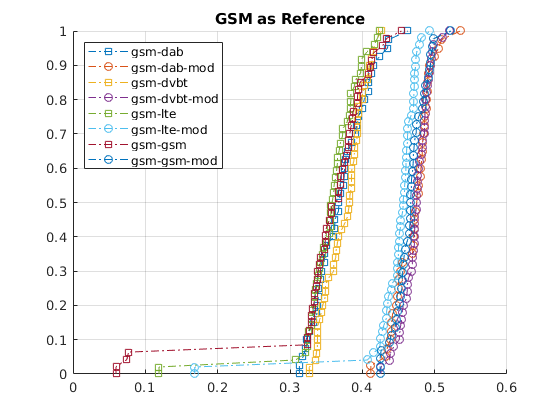

% Plotting
figure(); 
grid on; hold on;
[h{1},x{1}] = ecdf(gsm(1).in10.corr); [hm{1},xm{1}] = ecdf(gsm(1).in10m.corr);
[h{2},x{2}] = ecdf(gsm(2).in10.corr); [hm{2},xm{2}] = ecdf(gsm(2).in10m.corr);
[h{3},x{3}] = ecdf(gsm(3).in10.corr); [hm{3},xm{3}] = ecdf(gsm(3).in10m.corr);
[h{4},x{4}] = ecdf(gsm(4).in10.corr); [hm{4},xm{4}] = ecdf(gsm(4).in10m.corr);

for i = 1:4
    plot(x{i},h{i},'Marker',"square",'LineStyle',"-.");
    plot(xm{i},hm{i},'Marker',"o",'LineStyle',"-.");
end

legend('gsm-dab','gsm-dab-mod','gsm-dvbt','gsm-dvbt-mod','gsm-lte','gsm-lte-mod','gsm-gsm','gsm-gsm-mod','Location','northwest');
title('GSM as Reference');
hold off;

save('results/results_comparison',"dab","dvbt","gsm");